#### Define Parameters

Length of the rod $L$:

L = 1;

Integration time $T$:

T = 0.5;

Parameters of the steel rod: density $\rho$, radius $R$ and Young's modulus $E$:

rho = 7860;
R = 1e-2;
E = 210e9;
rod_par = [rho, R, E];
D = R^2;
C = E*R^2/rho

C = 2.6718e+03

Spatial $h$ and temporal $\tau$ steps

h = 0.01;
tau = 0.0001;

% Calculate the number of spatial steps
Nx = ceil(L / h) + 1;
% Adjust step h
h = L / (Nx - 1)

h = 0.0100

% Calculate the number of temporal steps
Nt = ceil(T / tau) + 1;
% Adjust step h
tau = T / (Nt - 1)

tau = 1.0000e-04

#### Initial conditions

Define initial conditions as

$u_0(x) = \frac{x}{\sqrt{\pi \cdot 0.02}} e^{-\frac{x^2}{2 \cdot 0.02^2}}$ for $x \in [-L/2, L/2]$

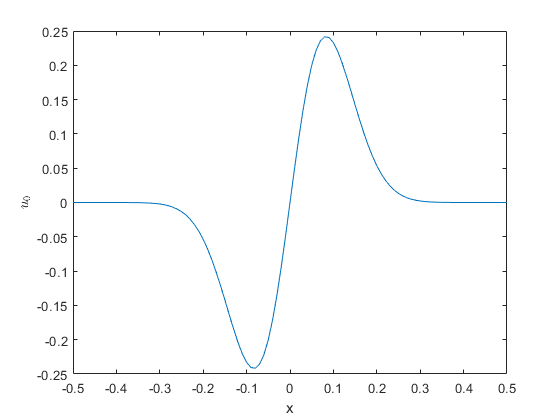

x = linspace(-L/2, L/2, Nx).';
t = linspace(0, T, Nt).';

U_0 = GaussianDistrib(-.25, .25, x);
U_0 = x.*U_0;

plot(x, U_0);
xlabel('x'); ylabel('$u_0$', "Interpreter","latex")

Also, set the first derivative w.r.t. time to be equal to zero: $\frac{\partial }{\partial t}u\left(x,0\right)=0$.

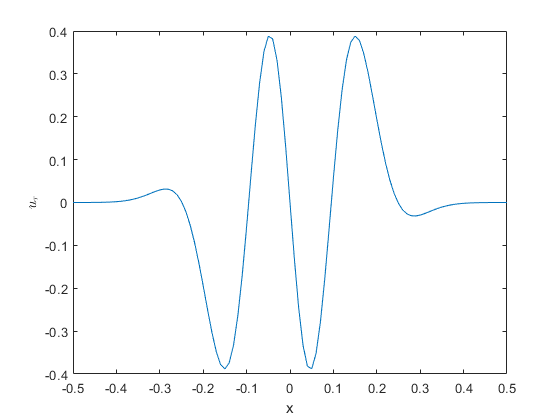

U_1 = 0 * U_0;
U_2 = u_tau_function(h, D, C, U_0);
U_tau = U_0 + U_1*tau + U_2*tau^2/2;

plot(x, U_tau);
xlabel('x'); ylabel('$u_\tau$', "Interpreter","latex")